load HCVEgyptData.mat
disp(HCV)

    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       BaselinehistologicalGrading    Baselinehistologicalstaging
    ___    ______    ___    _____    ________

class(HCV)

ans = 'table'

size(HCV)

ans =         1385          29


sum(sum(ismissing(HCV)))

ans = 0

arr=table2array(HCV);

% Remove outliers
[cdata,tf]=rmoutliers(arr(:,[1,3,11:27]))

cdata =           46          29       12101     4429425          10      129367          91         123          95          75         113          57         123          44       40620      538635      637056      336804       31085
          49          33        6490     4794631          10      146457          43          64         109          80          88          48          77          33     1041941      449939      585688      744463      582301
          58          22       11785     3882456          15      131228          66         104         121          96          65          73         114          29     1157452     1086852           5           5           5
          42          26       11620     4747333          12      177261          78          57         113         118         107          84          80          28      325694     1034008      275095      214566      635157
          48          30        7335     4405941          11      216176    

tf = 1385×1 logical array
   1
   0
   1
   0
   1
   0
   0
   0
   0
   0


for i=1:1385
    if tf(i)==1
        arr(i,:)=[];
    end
end
arr

arr =           46           1          29           1           2           2           1           2           2           1       12101     4429425          10      129367          91         123          95          75         113          57         123          44       40620      538635      637056      336804       31085           4           2
          57           1          33           2           2           2           2           1           1           1        4178     4621191          12      151522         113          49          95         107         116           5           5           5      571148      661346           5      735945      558829           4           4
          59           1          32           1           1           2           1           2           2           2        3661     4606375          11      187684          99         104          67          48         120          94          90          30      660410      738756     373

dat=array2table(arr,'VariableNames',HCV.Properties.VariableNames)

dat = 1381×29 table
    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       BaselinehistologicalGrading    Baselinehistologicalstaging
    ___    ______    ___    _____

% Advanced fibrosis yes or no => stage=3/4
y=arr(:,29)

y =      2
     4
     1
     4
     3
     2
     2
     2
     1
     1


sum(arr(:,29)>2)

ans = 715

length(arr)

ans = 1381

y(y<3)=0;
y(y>2)=1;
[arr(:,29) y(:,1)]

ans =      2     0
     4     1
     1     0
     4     1
     3     1
     2     0
     2     0
     2     0
     1     0
     1     0


y=array2table(y,"VariableNames",{'Stage'})

y = 1381×1 table
    Stage
    _____

      0  
      1  
      0  
      1  
      1  
      0  
      0  
      0  
      0  
      0  
      0  
      0  
      0  
      1  
      1  
      1  


dat=[dat(:,1:27) y]

dat = 1381×28 table
    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       Stage
    ___    ______    ___    _____    _____________    ________    

dat_arr=table2array(dat)

dat_arr =           46           1          29           1           2           2           1           2           2           1       12101     4429425          10      129367          91         123          95          75         113          57         123          44       40620      538635      637056      336804       31085           0
          57           1          33           2           2           2           2           1           1           1        4178     4621191          12      151522         113          49          95         107         116           5           5           5      571148      661346           5      735945      558829           1
          59           1          32           1           1           2           1           2           2           2        3661     4606375          11      187684          99         104          67          48         120          94          90          30      660410      738756     3731527      338946    

%Data normalization
dat_arr=normalize(dat_arr,'range')

dat_arr =     0.4828         0    0.5385         0    1.0000    1.0000         0    1.0000    1.0000         0    1.0000    0.5100         0    0.2724    0.5843    0.9438    0.6292    0.4045    0.8315    0.4228    0.9593    0.9750    0.0338    0.4482    0.1707    0.4166    0.0384         0
    0.8621         0    0.8462    1.0000    1.0000    1.0000    1.0000         0         0         0    0.1303    0.6695    0.4000    0.4384    0.8315    0.1124    0.6292    0.7640    0.8652         0         0         0    0.4755    0.5503         0    0.9103    0.6896    1.0000
    0.9310         0    0.7692         0         0    1.0000         0    1.0000    1.0000    1.0000    0.0735    0.6572    0.2000    0.7094    0.6742    0.7303    0.3146    0.1011    0.9101    0.7236    0.6911    0.6250    0.5498    0.6147    1.0000    0.4193    0.2997         0
    0.8966    1.0000         0    1.0000    1.0000    1.0000         0    1.0000    1.0000         0    0.9653    0.0549    1.0000    0.2864    0.3

dat=array2table(dat_arr,'VariableNames',dat.Properties.VariableNames)

dat = 1381×28 table
      Age       Gender      BMI       Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain      WBC         RBC       HGB      Plat       AST1       ALT1       ALT4       ALT12      ALT24       ALT36      ALT48     ALTafter24w    RNABase       RNA4       RNA12       RNAEOT      RNAEF      Stage
    ________    ______    ________    _____    _____________    

% fitlm and add and remove using step
mdl1=fitlm(dat,'ResponseVar','Stage','CategoricalVars',{'Diarrhea','Epigastricpain','Fatiguegeneralizedboneache','Fever','Gender','Headache','Jaundice','NauseaVomting'})

mdl1 = Linear regression model:
    Stage ~ 1 + Age + Gender + BMI + Fever + NauseaVomting + Headache + Diarrhea + Fatiguegeneralizedboneache + Jaundice + Epigastricpain + WBC + RBC + HGB + Plat + AST1 + ALT1 + ALT4 + ALT12 + ALT24 + ALT36 + ALT48 + ALTafter24w + RNABase + RNA4 + RNA12 + RNAEOT + RNAEF

Estimated Coefficients:
                                     Estimate        SE        tStat        pValue  
                                    __________    ________    ________    __________

    (Intercept)                         0.5414     0.12464      4.3437    1.5058e-05
    Age                              -0.042526    0.044582    -0.95389       0.34031
    Gender_1                          0.041713    0.027045      1.5424       0.12322
    BMI                               -0.

newmdl1=step(mdl1)

1. Adding Headache:HGB, FStat = 6.9063, pValue = 0.0086867


newmdl1 = Linear regression model:
    Stage ~ 1 + Age + Gender + BMI + Fever + NauseaVomting + Diarrhea + Fatiguegeneralizedboneache + Jaundice + Epigastricpain + WBC + RBC + Plat + AST1 + ALT1 + ALT4 + ALT12 + ALT24 + ALT36 + ALT48 + ALTafter24w + RNABase + RNA4 + RNA12 + RNAEOT + RNAEF + Headache*HGB

Estimated Coefficients:
                                     Estimate        SE        tStat        pValue  
                                    __________    ________    ________    __________

    (Intercept)                        0.47374     0.12701        3.73    0.00019938
    Age                              -0.039696    0.044498    -0.89207       0.37251
    Gender_1                          0.043959       0.027      1.6281       0.10373
    BMI                               -0

[Xtrain, Ytrain, Xtest, Ytest]=trainTestSplit(dat_arr(:,1:27),dat_arr(:,28),0.7);

%Stepwiselm
mdls1=stepwiselm(Xtrain,Ytrain,'NSteps',100)

1. Adding x27, FStat = 6.3713, pValue = 0.011758
2. Adding x10, FStat = 5.3272, pValue = 0.021206
3. Adding x3, FStat = 4.5751, pValue = 0.032691
4. Adding x10:x27, FStat = 4.1864, pValue = 0.041021


mdls1 = Linear regression model:
    y ~ 1 + x3 + x10*x27

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     0.59934    0.043512     13.774    1.5787e-39
    x3             -0.11799    0.051172    -2.3058      0.021333
    x10            -0.14477    0.047047    -3.0773     0.0021482
    x27             0.01886    0.070727    0.26666       0.78979
    x10:x27         0.19991    0.097703     2.0461      0.041021


Number of observations: 967, Error degrees of freedom: 962
Root Mean Squared Error: 0.496
R-squared: 0.021,  Adjusted R-Squared: 0.0169
F-statistic vs. constant model: 5.15, p-value = 0.000418

pred_s=round(predict(mdls1,Xtest))

pred_s =      1
     1
     0
     1
     0
     1
     1
     1
     1
     0


[pred_s Ytest]

ans =      1     0
     1     0
     0     1
     1     1
     0     1
     1     0
     1     0
     1     0
     1     1
     0     1


a_s=sum(pred_s==Ytest)/length(Ytest)

a_s = 0.5314

p_s=sum(pred_s==1 & Ytest==1)/sum(pred_s==1)

p_s = 0.5534

m_s=mean(abs(pred_s-Ytest))

m_s = 0.4686

c_s=corr(pred_s,Ytest)

c_s = 0.0453

RFmodel=TreeBagger(100,Xtrain,Ytrain,'MinLeafSize',10,'OOBPrediction',"on",'OOBPredictorImportance',"on")

RFmodel =   TreeBagger
Ensemble with 100 bagged decision trees:
                    Training X:             [967x27]
                    Training Y:              [967x1]
                        Method:       classification
                 NumPredictors:                   27
         NumPredictorsToSample:                    6
                   MinLeafSize:                   10
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    1
                     Proximity:                   []
                    ClassNames:             '0'             '1'

  Properties, Methods


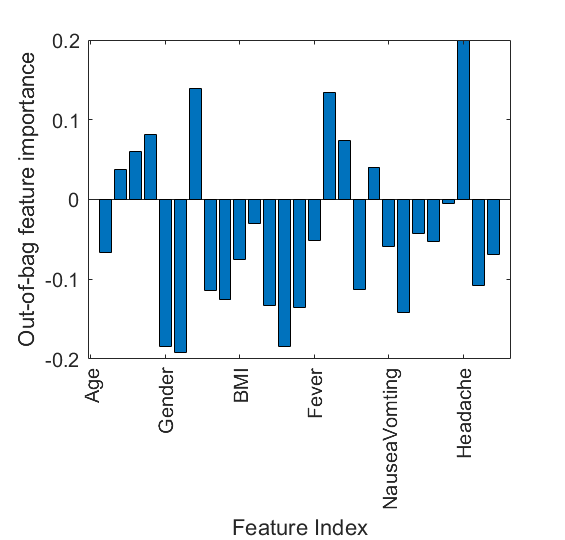

bar(RFmodel.OOBPermutedPredictorDeltaError)
xlabel('Feature Index')
ylabel('Out-of-bag feature importance')
xticklabels(dat.Properties.VariableNames(1:27))
xtickangle(90)

Ypred=predict(RFmodel,Xtest) % RF gives output in cell array format

Ypred = 414×1 cell array
    {'1'}
    {'0'}
    {'0'}
    {'1'}
    {'1'}
    {'0'}
    {'0'}
    {'1'}
    {'1'}
    {'1'}
    {'0'}
    {'1'}
    {'1'}
    {'1'}
    {'0'}
    {'1'}
    {'1'}
    {'0'}
    {'0'}
    {'0'}
    {'1'}
    {'1'}
    {'0'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'0'}
    {'1'}
    {'1'}


Ypred=categorical(Ypred) % cell array to categorical array

Ypred = 414×1 categorical array
     1 
     0 
     0 
     1 
     1 
     0 
     0 
     1 
     1 
     1 
     0 
     1 
     1 
     1 
     0 
     1 
     1 
     0 
     0 
     0 
     1 
     1 
     0 
     1 
     1 
     1 
     1 
     0 
     1 
     1 


sum(Ypred==categorical(Ytest))/length(Ytest) % accuracy

ans = 0.4879

net=fitnet(10,'trainbr');
net=train(net,Xtrain',Ytrain');
y=net(Xtest');
perf = perform(net,y,Ytest')

perf = 0.2531

sum(round(y')==Ytest)/length(Ytest)

ans = 0.5242

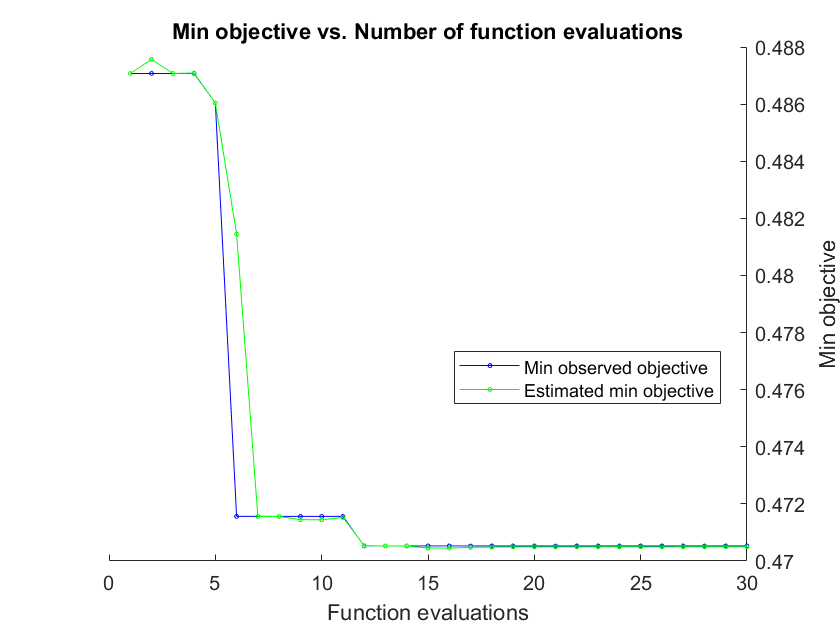

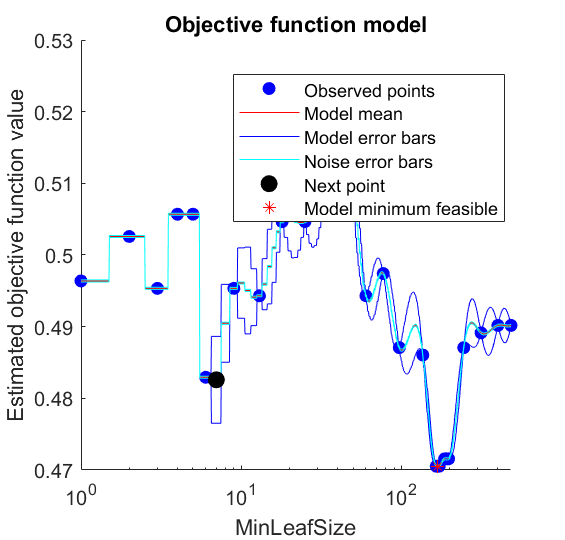

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.48707 |     0.47696 |     0.48707 |     0.48707 |           97 |
|    2 | Accept |     0.49638 |     0.24754 |     0.48707 |     0.48757 |            1 |
|    3 | Accept |     0.49018 |     0.13568 |     0.48707 |     0.48707 |          400 |
|    4 | Accept |     0.50465 |     0.18539 |     0.48707 |     0.48709 |           18 |
|    5 | Best   |     0.48604 |     0.13928 |     0.48604 |     0.48604 |          136 |
|    6 | Best   |     0.47156 |     0.14677 |     0.47156 |     0.48145 |          186 |
|    7 | Accept |     0.47156 |     0.14567 |     0.47156 |     0.47156 |          197 |
|    8 | Accept |    

mdl3 =   ClassificationTree
                       PredictorNames: {1×27 cell}
                         ResponseName: 'Y'
                CategoricalPredictors: [7 10 8 4 2 6 9 5]
                           ClassNames: [0 1]
                       ScoreTransform: 'none'
                      NumObservations: 967
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]


  Properties, Methods


mdl3 = fitctree(Xtrain,Ytrain,'OptimizeHyperparameters','auto','PredictorNames',dat.Properties.VariableNames(1:27),'CategoricalPredictors',{'Diarrhea','Epigastricpain','Fatiguegeneralizedboneache','Fever','Gender','Headache','Jaundice','NauseaVomting'})

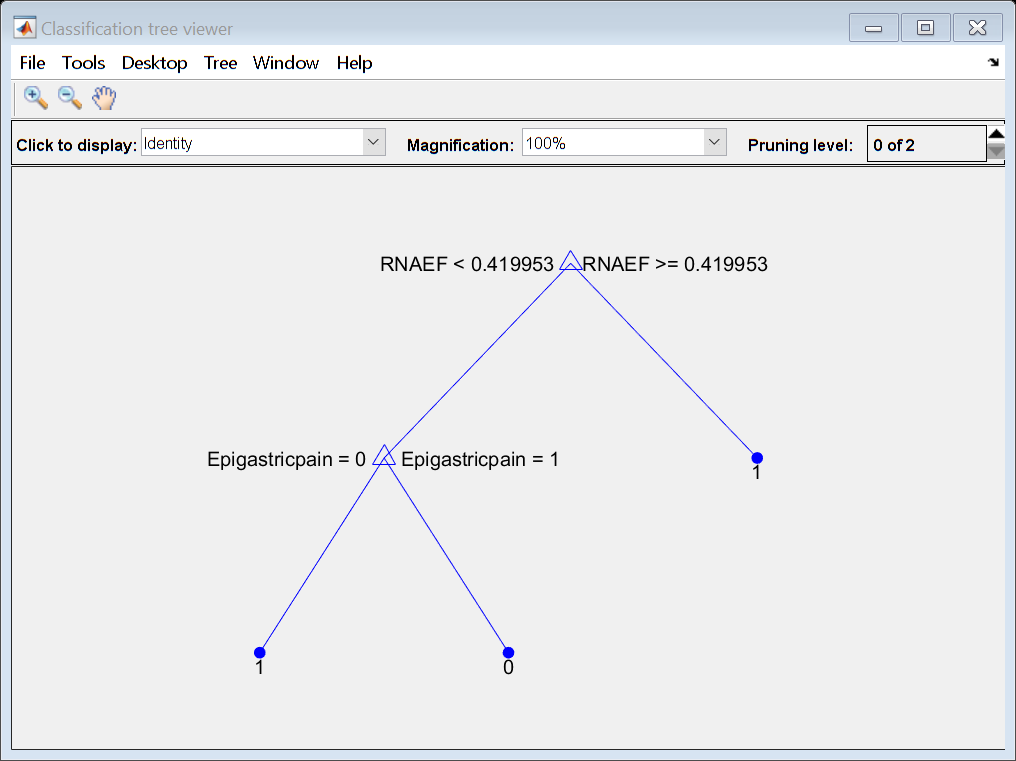

view(mdl3,'mode','graph')

pred=predict(mdl3, Xtest)

pred =      0
     1
     0
     1
     0
     1
     1
     1
     0
     1


sum(pred==Ytest)/length(Ytest)

ans = 0.5121

imp=predictorImportance(mdl3)

imp =          0         0         0         0         0         0         0         0         0    0.0026         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0026


array2table(imp',"RowNames",dat.Properties.VariableNames(1:27))

ans = 27×1 table
                                    Var1  
                                  ________

    Age                                  0
    Gender                               0
    BMI                                  0
    Fever                                0
    NauseaVomting                        0
    Headache                             0
    Diarrhea                             0
    Fatiguegeneralizedboneache           0
    Jaundice                             0
    Epigastricpain                0.002578
    WBC                                  0
    RBC                                  0
    HGB                                  0
    Plat                                 0
    AST1      

mdl4=fitlm(Xtrain(:,[10,27]),Ytrain,'CategoricalVars','x1')

mdl4 = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate        SE        tStat       pValue  
                   _________    ________    _______    __________

    (Intercept)      0.50171    0.028154     17.821    1.2721e-61
    x1_1           -0.073984    0.032054    -2.3081      0.021206
    x2               0.12905    0.048801     2.6444     0.0083167


Number of observations: 967, Error degrees of freedom: 964
Root Mean Squared Error: 0.498
R-squared: 0.012,  Adjusted R-Squared: 0.00997
F-statistic vs. constant model: 5.86, p-value = 0.00294

pred=round(predict(mdl4,Xtest(:,[10,27])))

pred =      0
     1
     0
     1
     0
     1
     1
     1
     0
     0


sum(pred==Ytest)/length(Ytest)

ans = 0.5048

m = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)    0.57602     0.030406     18.944    2.7107e-68
    x1             -0.1417     0.051301    -2.7622     0.0058508


Number of observations: 967, Error degrees of freedom: 965
Root Mean Squared Error: 0.499
R-squared: 0.00784,  Adjusted R-Squared: 0.00682
F-statistic vs. constant model: 7.63, p-value = 0.00585

p =      1
     0
     1
     1
     1
     1
     0
     0
     1
     0


ans = 0.5121

% Based on fitctree
mdl3 = fitctree(Xtrain(:,[10,27]),Ytrain,'PredictorNames',dat.Properties.VariableNames(10,27),dat.Properties.VariableNames(10))

Index in position 1 exceeds array bounds (must not exceed 1).

view(mdl3,'mode','graph')
pred=predict(mdl3, Xtest(:,[10,27]))
sum(pred==Ytest)/length(Ytest)
imp=predictorImportance(mdl3)
array2table(imp',"RowNames",dat.Properties.VariableNames(10,27))